# Aproximare MCMMP

## Recensământul SUA

Datele de mai jos au fost înregistrate de US Census între 1900 și 2010

%CENSUS - example with census data
%          exponetial fit

%data
y = [ 75.995  91.972 105.711 123.203 131.669 150.697 ...
    179.323 203.212 226.505 249.633 281.422 308.786]';

t = (1900:10:2010)';   % census years

Dorim să modelăm datele și să facem predicții pentru anii 1975 și 2015


x = (1890:1:2019)';    % evaluation years
w = [1975,2015];              % prediction year

Vom modela datele printr-un model exponențial


$$y=Ke^{\lambda x}$$


## Fitting exponential

coeficienții


cs=polyfit(t,log(y),1);
K=exp(cs(2)) 

K =    3.2746e-09


lambda=cs(1)

lambda =      0.012595


predicțiile:

fm=@(t) K*exp(lambda*t);
zs=fm(x);
est=fm(w);

Reprezentarea grafică

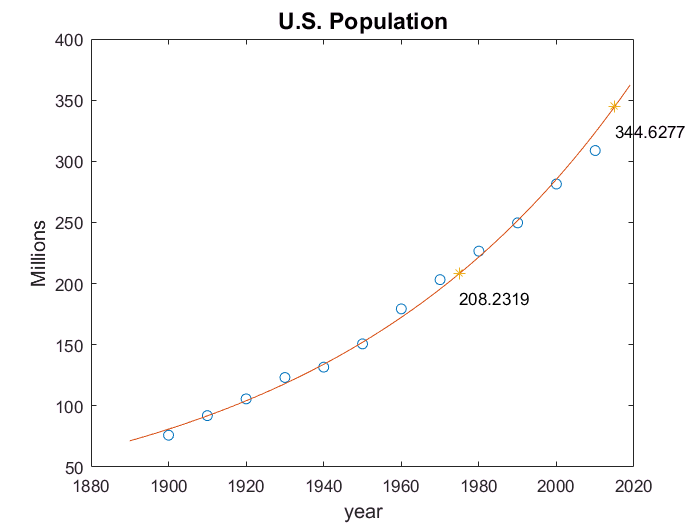

plot(t,y,'o',x,zs,'-',w,est,'*')
for i=1:length(w)
    text(w(i),est(i)-20,num2str(est(i)))
end
title('U.S. Population', 'FontSize', 14)
xlabel('year', 'FontSize', 12)
ylabel('Millions', 'FontSize', 12)